# Chess set materials and views

ISET3d-v4  (V3) enables users to create spectral irradiance images.  These can be  passed through the human optics to calculate cone excitations. This script illustrates the calulcation using ISET3d-v4 in connection with ISETCam, rather than ISETBio.  The reason I used that  the HDR pulldown. 

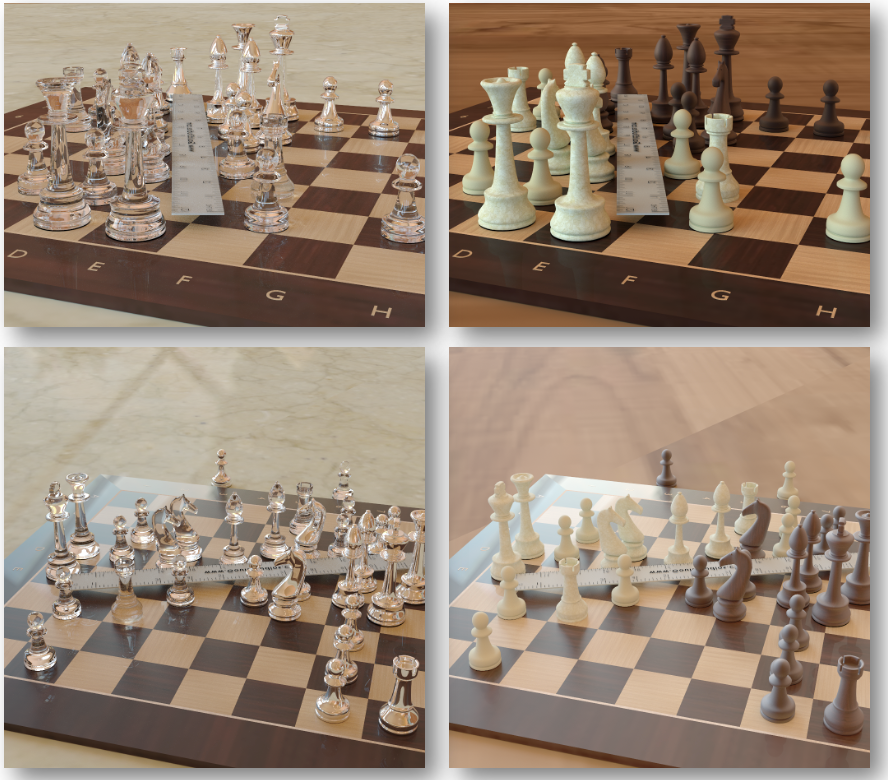

BW should put the HDR pulldown (and all the ISETCam improvements) into ISETBio scene and oi functions.

The script will run with ISETBio.  The appearance of the pieces and lighting, however, appears to vary between PBRT V3 and V4.

**See also**

  isetspitschan directory

## Initialize for ISET3d

ieInit
if ~piDockerExists, piDockerConfig; end
highRes = true;

## Read the chess set model

chessR = piRecipeDefault('scene name','ChessSet');

Read 9 materials and 3 textures..


### Add some new materials to the scene so we can change the chess set and board materials.

chessR = piMaterialsInsert(chessR);


Scene materials: ChessSet
-------------------------------
                name               type      
          ________________    _______________

    1     <undefined>         coateddiffuse  
    2     Black_glossy        coateddiffuse  
    3     Filt_004            diffuse        
    4     Gray                diffuse        
    5     Gray_glossy         coateddiffuse  
    6     GroundMaterial      coateddiffuse  
    7     Lyse_brikker_008    coateddiffuse  
    8     Mrke_brikker_004    coateddiffuse  
    9     Mtl                 coateddiffuse  
    10    Mtl8                diffuse        
    11    Red                 diffuse        
    12    Red_glossy          coateddiffuse  
    13 

### Add several points of view.  

We can vary these later, but first we pick one and render.

toObject = [0.03 0.05 -0.01];   % A good object
chessR.set('to',toObject);

% Top view, looking forward
topForward = [-0.0000  0.150   -0.6000];

% Top view, looking back
topBackward = [0 0.4 0.5];

% Side view
% sideView = [0.7 0.2 -0.1];
sideView = [0.5138    0.15   -0.40];

% Top view, lower, forward
topForward2 = [-0.0000  0.18   -0.6000];

% The field of view in degrees
chessR.set('fov',70);

### Choose the resolution for the rendering

if ~highRes
    chessR.set('rays per pixel',64);
    chessR.set('film resolution',[256 256]);
    chessR.set('n bounces',3);
else
    chessR.set('rays per pixel',512);
    chessR.set('film resolution',[768 768]);
    chessR.set('n bounces',5);
end

### List the default objects and materials

% This is a list of the objects tha make up the chess set.
chessR.show('objects');

                                                  material             positions (m)           sizes (m)     
                                            ____________________    ___________________    __________________

    0006ID_001_ChessSet_mesh_00001_O        {'Lyse_brikker_008'}    {'0.02 0.05 0.01' }    {'NaN NaN NaN'   }
    0009ID_001_ChessSet_mesh_00002_O        {'Mrke_brikker_004'}    {'0.02 0.05 0.01' }    {'NaN NaN NaN'   }
    0012ID_001_ChessSet_mesh_00003_O        {'Mrke_brikker_004'}    {'0.07 0.05 0.01' }    {'NaN NaN NaN'   }
    0015ID_001_ChessSet_mesh_00004_O        {'Filt_004'        }    {'0.04 0.05 -0.05'}    {'NaN NaN NaN'   }
    0018ID_001_ChessSet_mesh_00005_O        {'Filt_004'        }    {'0.02 0.05 0.01' }    {'NaN NaN NaN'   }
    0021ID_001_ChessSet_mesh_00006

### Render

[~,results] = piWRS(chessR,'show',false,'rgb',true);

*** Rendering time for ChessSet:  43.0 sec ***



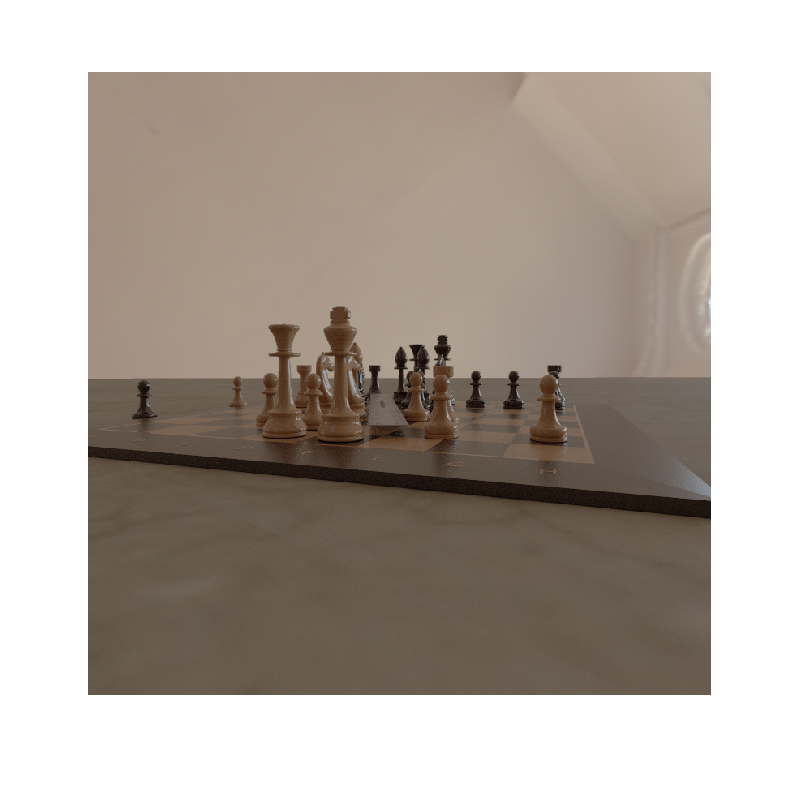

ieNewGraphWin; imagescRGB(results.rgb.^0.5);

## Modify the lights materials

### Change the ambient lighting to be a skymap from a room

chessR.set('light', 'all', 'delete');
chessR.set('skymap','room.exr');
% We can insert code to rotate the skymap around.

### Change the materials to glass and mirror

% We change the material of the light and dark pieces.
% We also change the number of bounces so the glass and metal look
% good.
names = chessR.get('object names no id');
for ii=1:numel(names)
    if piContains(names{ii},'mesh')
        thisMaterial = chessR.get('asset',names{ii},'material name');
        if piContains(thisMaterial,'Lyse')
            chessR.set('asset',names{ii},'material name','glass');
        elseif piContains(thisMaterial,'Mrke')
            chessR.set('asset',names{ii},'material name','mirror');
        end
    end
end

## Do the rendering

chessR.set('from',topForward);
chessR.set('object distance',0.35);
if ~highRes
    chessR.set('rays per pixel',64);
    chessR.set('film resolution',[256 256]);
    chessR.set('n bounces',2);
else
    chessR.set('rays per pixel',512);
    chessR.set('film resolution',[768 768]);
    chessR.set('n bounces',5);
end
[~,results] = piWRS(chessR,'show',false,'rgb',true);

*** Rendering time for ChessSet:  49.1 sec ***



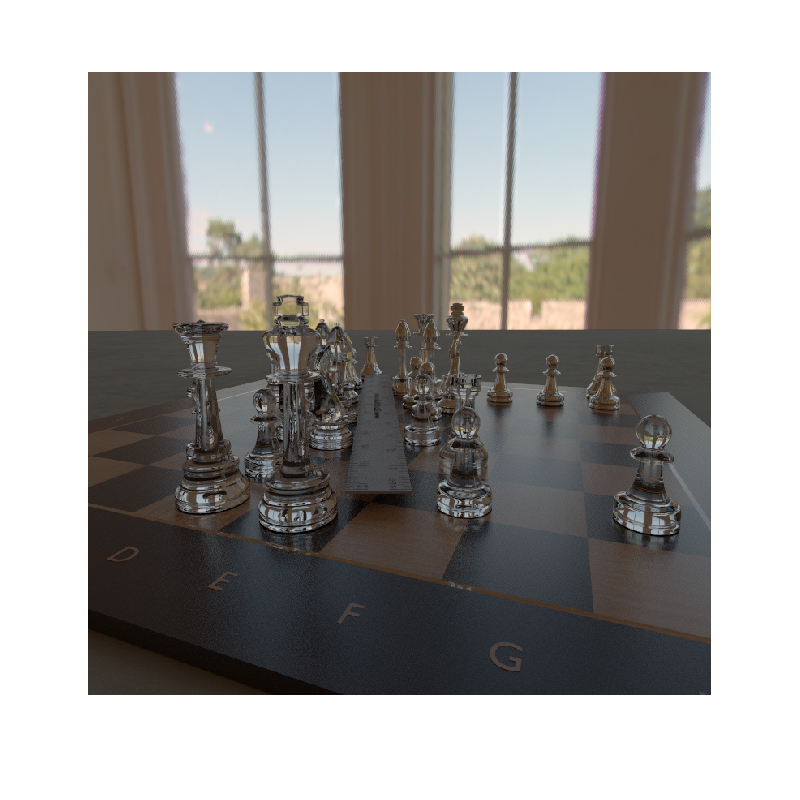

ieNewGraphWin; imagescRGB(results.rgb.^0.5);

## Alter the materials and point of view

Now we change the chess set pieces to marble and mahogany.

chessR = piRecipeDefault('scene name','chess set');

Read 9 materials and 3 textures..


chessR = piMaterialsInsert(chessR);


Scene materials: ChessSet
-------------------------------
                name               type      
          ________________    _______________

    1     <undefined>         coateddiffuse  
    2     Black_glossy        coateddiffuse  
    3     Filt_004            diffuse        
    4     Gray                diffuse        
    5     Gray_glossy         coateddiffuse  
    6     GroundMaterial      coateddiffuse  
    7     Lyse_brikker_008    coateddiffuse  
    8     Mrke_brikker_004    coateddiffuse  
    9     Mtl                 coateddiffuse  
    10    Mtl8                diffuse        
    11    Red                 diffuse        
    12    Red_glossy          coateddiffuse  
    13 

### Change the camera position but still look at the same object.

chessR.set('from',topBackward);
chessR.set('to',toObject);

chessR.set('light', 'all', 'delete');
chessR.set('skymap','room.exr');                

### Change the material again

names = chessR.get('object names no id');
for ii=1:numel(names)
    if piContains(names{ii},'mesh')
        thisMaterial = chessR.get('asset',names{ii},'material name');
        if piContains(thisMaterial,'Lyse')
            chessR.set('asset',names{ii},'material name','wood001');
        elseif piContains(thisMaterial,'Mrke')
            chessR.set('asset',names{ii},'material name','glass');            
        end
    end
end

% These materials worked, too.
% chessR.set('material','planeTan','kd val','wood001');
% chessR.set('material','planeTan','kd val','wood002');
% chessR.set('material','planeTan','kd val','marbleBeige');

n = chessR.get('object names');
ii = find(piContains(n,'GroundMaterial'));
chessR.set('asset',n{ii},'material name','brickwall001');

### Have a look at the new materials

chessR.show('objects');

                                                  material             positions (m)           sizes (m)     
                                            ____________________    ___________________    __________________

    0004ID_001_ChessSet_mesh_00001_O        {'wood001'         }    {'0.02 0.05 0.01' }    {'NaN NaN NaN'   }
    0007ID_001_ChessSet_mesh_00002_O        {'glass'           }    {'0.02 0.05 0.01' }    {'NaN NaN NaN'   }
    0010ID_001_ChessSet_mesh_00003_O        {'glass'           }    {'0.07 0.05 0.01' }    {'NaN NaN NaN'   }
    0013ID_001_ChessSet_mesh_00004_O        {'Filt_004'        }    {'0.04 0.05 -0.05'}    {'NaN NaN NaN'   }
    0016ID_001_ChessSet_mesh_00005_O        {'Filt_004'        }    {'0.02 0.05 0.01' }    {'NaN NaN NaN'   }
    0019ID_001_ChessSet_mesh_00006

### Render with the new materials and point of view

if ~highRes
    chessR.set('rays per pixel',64);
    chessR.set('film resolution',[256 256]);
    chessR.set('n bounces',2);
else
    chessR.set('rays per pixel',512);
    chessR.set('film resolution',[768 768]);
    chessR.set('n bounces',5);
end
[~,results] = piWRS(chessR,'show',false,'rgb',true);

*** Rendering time for ChessSet:  59.7 sec ***



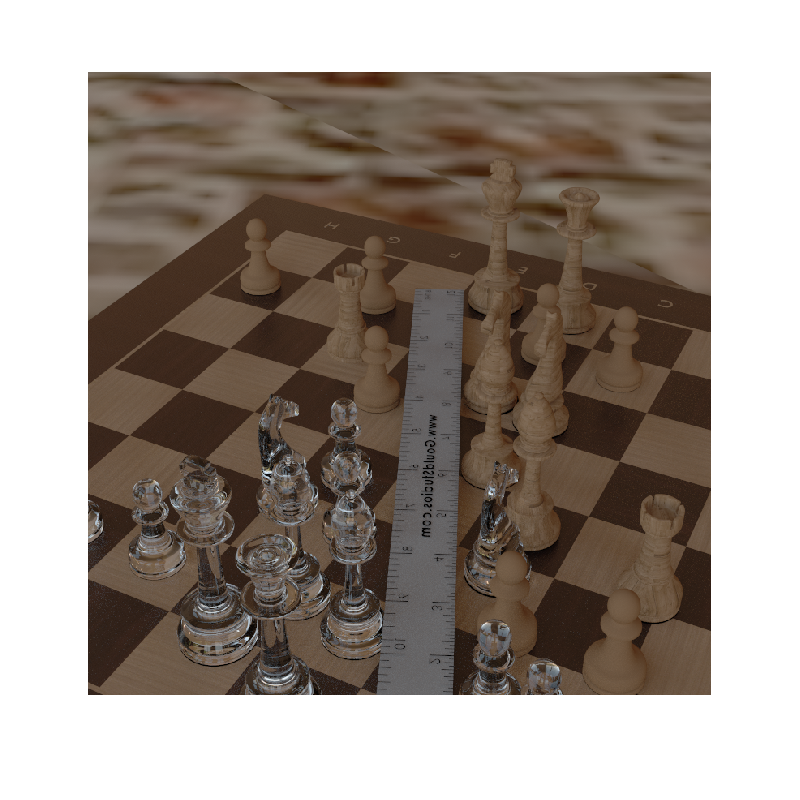

ieNewGraphWin; imagescRGB(results.rgb.^0.5);

## END